# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D');
load('WS_VAB_wb_0_5.mat','A','B','C','D');

## Analisi stabilità

Studio dell'asintotica stabilità tramite gli autovalori della matrice A: come noto dalla teoria, il sistema è asintoticamente stabile se gli autovalori hanno tutti parte reale negativa; è instabile invece se è presente almeno un autovalore con parte reale strettamente positiva.

% Passing from symbolic to real values
A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

sys = ss(A_real,B_real,C_real,D_real) % Same of G
lambda = eig(A_real)

Come si vede il sistema non è asintoticamente per la presenza di autovalori con parte reale non strettamente positiva.

pzplot(sys)
%rlocus(sys)
M_r = ctrb(sys) % Matrice di raggiungibilità
rank(M_r)
M_o = obsv(sys) % Matrice di osservabilità
rank(M_o)

Si vede come il sistema, in anello aperto, non sia asintoticamente stabile (come previsto), dalle analisi sugli autovalori e sui poli.

Lo stato del sistema, nel nostro caso, risulta essere accessibile, poichè sono misurazioni che possono essere direttamente realizzate per mezzo di tecniche di sensor fusion.

Per ora vogliamo controllare solamente l'angolo $\theta \;$, e quindi ci poniamo in una condizione di sistema SISO (input la coppia motrice, output l'accelerazione $\ddot{\theta \;}$):


$${\left\{\begin{array}{c}
x\left(t\right)=Ax{\left(t\right)}+Bu\left(t\right)\\
y{\left(t\right)}=Cx{\left(t\right)}+Du\left(t\right)
\end{array}\right)}$$


Utilizzando la legge di controllo


$$u{\left(t\right)}=-Kx{\left(t\right)}+w{\left(t\right)}$$


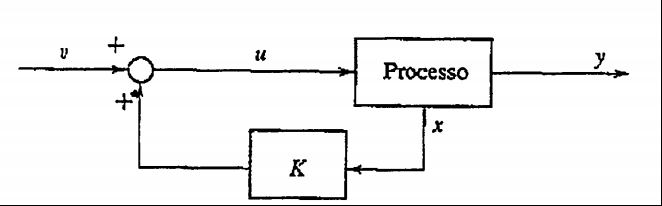

Per la scelta della matrice K


$$x{\left(t\right)}=Ax{\left(t\right)}+Bu{\left(t\right)}=Ax{\left(t\right)}+B{\left(-Kx{\left(t\right)}+w{\left(t\right)}\right)}\to legge\ di\ controllo\ in\ anello\ chiuso$$



$$=Ax{\left(t\right)}-BKx{\left(t\right)}+Bw\left(t\right)={\left(A-BK\right)}x{\left(t\right)}+Bw{\left(t\right)}$$



$$A_{cl} =A-BK=matrice\;di\;stato\;in\;closed-loop$$


## Posizionamento dei poli

Per andare a calcolare questo vettore dei poli K, possiamo utilizzare il comando ***place***.

Per fare ciò ci atteniamo ai parametri richiesti per entrambi i poli, ovvero:

- Smorzamento $=\xi =0\ldotp 7$

- Pulsazione naturale polo $=\omega {\;}_{n\;} =2\bullet \pi \bullet f_{\textrm{propria}}$

In generale sappiamo che


$$G{\left(S\right)}=\frac{1}{s^2 +2\xi \omega {\;}_n s+\omega {\;}_n^{2\;} }=\frac{1}{1+2∙\frac{\textrm{𝜉}}{{\textrm{𝜔}}_n }s+\frac{s^2 }{{\textrm{𝜔}}_n^2 }}$$


Per trovare i poli mi basta risolvere l'equazione al denominatore, trovando i valori di s che l'annullano:

syms xsi wn1 wn2 s;
% Definisco le funzioni di trasferimento
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0;
dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0;
sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

% fn1 = 20; % [Hz]
fn1 = 0.1; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

% fn2 = 2; % [Hz]
fn2 = 0.01; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli (

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1});
pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2});
pol_1_real = double(pol_1)
pol_2_real = double(pol_2)
K = place(A_real,B_real,[pol_1_real', pol_2_real'])
save('K.mat','K');

Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_real-B_real * K;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl)
sys_cl = ss(A_cl,B_real,C_real,D_real);
rlocus(sys_cl)
pzmap(sys_cl)

Posso utilizzare un'altra tecnica per realizzare il place dei poli (LQR - Regolatore Lineare Quadratico) che rappresenta una soluzione ottima per il pole placement:

Q = eye(4);
R = 1;
K_lqr = lqr(A_real,B_real,Q,R)
K = K_lqr

## Sistema lineare

### Simulazione senza controllo

% Initial condition for open loop model
x_0 = [0; 0; 5 * pi / 180; 0];

control_on = 0;
t_end = 2;
Ts = 1/100;

simOut = sim('VAB_Linear_PolePlacement');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;

figure
hold on
plot(tout, thetaClamped)
plot(tout, phiClamped)
xlabel('Time [s]')
ylabel('Angles clamped[°]')
legend('theta','phi');
title('Angle - linearized no control')

figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m^2]')
title('Torque - linearized no control')

figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linearized no control')
legend('phi', 'phi punto', 'theta', 'theta punto');

% for i=1:size(completeState,1)
%     call_plot(completeState(i,:))
% end

### Simulazione con controllo

% Initial condition for open loop model
x_0 = [0; 0; 5 * pi / 180; 0];

control_on = 1;
t_end = 150;
Ts = 1/100;

simOut = sim('VAB_Linear_PolePlacement');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;

figure
hold on
plot(tout, thetaClamped)
plot(tout, phiClamped)
xlabel('Time [s]')
ylabel('Angles clamped[°]')
legend('theta','phi');
title('Angle - linearized control on')

figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m^2]')
title('Torque - linearized control on')

figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linearized control on')
legend('phi', 'phi punto', 'theta', 'theta punto');

% for i=1:size(completeState,1)
%     call_plot(completeState(i,:))
% end

## **Sistema non lineare**

### **Simulazione senza controllo**

alpha = 0;
alpha_simulazione = double(alpha);
theta_iniziale = 15 *pi/180;
control_on = 0;
simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;

figure
hold on
plot(tout, thetaClamped)
plot(tout, phiClamped)
xlabel('Time [s]')
ylabel('Angles clamped[°]')
legend('theta','phi');
title('Angle - not linearized no control')

figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m^2]')
title('Torque - not linearized no control')

figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - not linearized no control')
legend('phi', 'phi punto', 'theta', 'theta punto');

### Simulazione con controllo

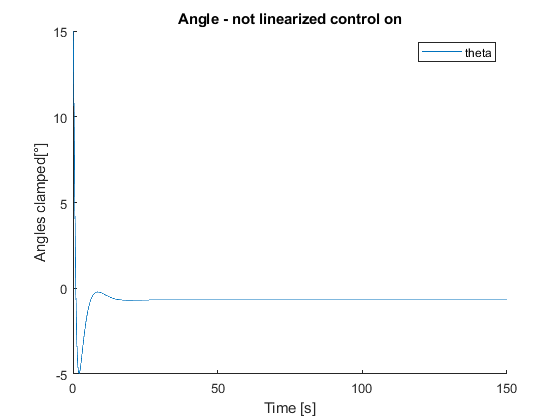

control_on = 1;
simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;

figure
hold on
plot(tout, thetaClamped)
xlabel('Time [s]')
ylabel('Angles clamped[°]')
legend('theta');
title('Angle - not linearized control on')

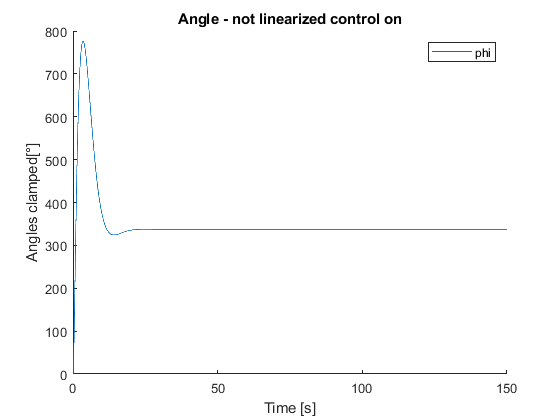


figure
hold on
plot(tout, phiClamped)
xlabel('Time [s]')
ylabel('Angles clamped[°]')
legend('phi');
title('Angle - not linearized control on')

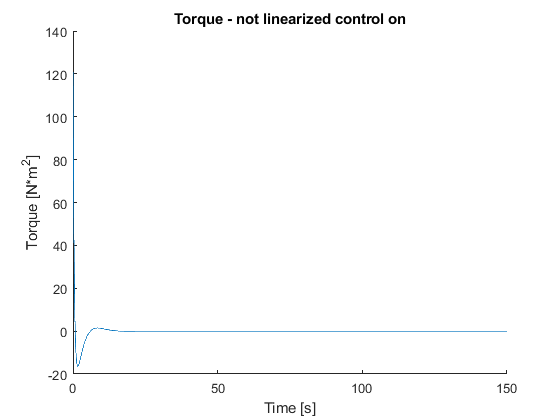


figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m^2]')
title('Torque - not linearized control on')

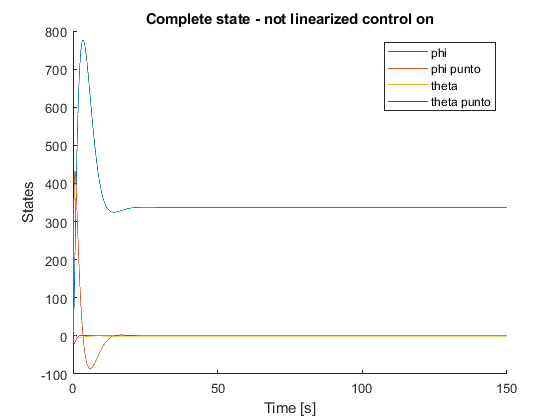


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - not linearized control on')
legend('phi', 'phi punto', 'theta', 'theta punto');

NB: State need to be defined in rad!

call_plot(completeState * pi / 180);

Error using pause
Operation terminated by user

Error in call_plot (line 15)
     pause(1/2000)